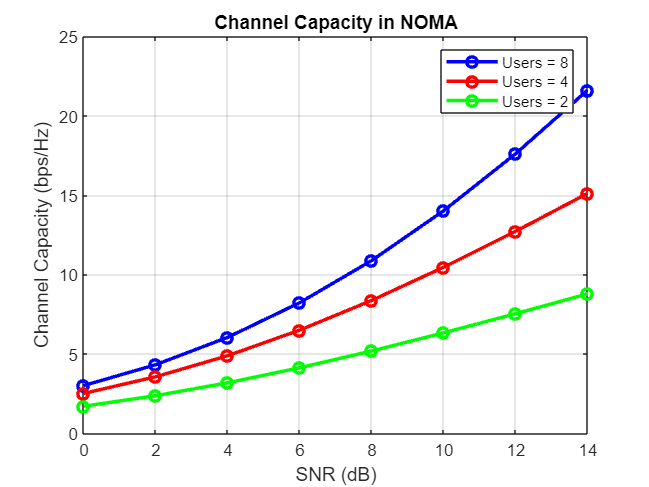

%------------------------SNR-------------------------
SNRdB = 0:2:14;
SNR = 10.^(SNRdB/10);
% disp(SNR)
numUsers = 8;

%--------------------Power Allocation----------------
powerAllocations = ones(1, numUsers);

for i=1:length(SNR)
    
    powerAllocations(i) = 1/SNR(i) ;
    % disp(powerAllocations)

end

%powerAllocations = 0 + (1-0) .* rand(8,1);
%disp(powerAllocations);

channelCapacity = zeros(1, length(SNRdB));

powerAllocations = powerAllocations / max(powerAllocations);


%-------------------Channel Capacity-----------------------

for i = 1:length(SNR)
    snr = SNR(i);
    
    userCapacity = zeros(1, numUsers);
    
    for user = 1:numUsers
        userCapacity(user) = log2(1 + powerAllocations(user) * snr);
    end
        
    channelCapacity(i) = sum(userCapacity);
end

%--------------------Plots------------------------

plot(SNRdB, channelCapacity, 'b-o', 'LineWidth', 2);

xlabel('SNR (dB)');
ylabel('Channel Capacity (bps/Hz)');
title('Channel Capacity in NOMA');
grid on;
hold on

%------------------------SNR-------------------------
SNRdB = 0:2:14;
SNR = 10.^(SNRdB/10);
% disp(SNR)
numUsers = 4;

%--------------------Power Allocation----------------
powerAllocations = ones(1, numUsers);

for i=1:length(SNR)
    
    powerAllocations(i) = 1/SNR(i) ;
    % disp(powerAllocations)

end


%powerAllocations = 0 + (1-0) .* rand(8,1);
%disp(powerAllocations);

channelCapacity = zeros(1, length(SNRdB));

powerAllocations = powerAllocations / max(powerAllocations);


%-------------------Channel Capacity-----------------------

for i = 1:length(SNR)
    snr = SNR(i);
    
    userCapacity = zeros(1, numUsers);
    
    for user = 1:numUsers
        userCapacity(user) = log2(1 + powerAllocations(user) * snr);
    end
        
    channelCapacity(i) = sum(userCapacity);
end

%--------------------Plots------------------------

plot(SNRdB, channelCapacity, 'r-o', 'LineWidth', 2);
legend('Users = 4');
hold on

%------------------------SNR-------------------------
SNRdB = 0:2:14;
SNR = 10.^(SNRdB/10);
% disp(SNR)
numUsers = 2;

%--------------------Power Allocation----------------
powerAllocations = ones(1, numUsers);

for i=1:length(SNR)
    
    powerAllocations(i) = 1/SNR(i) ;
    % disp(powerAllocations)

end


%powerAllocations = 0 + (1-0) .* rand(8,1);
%disp(powerAllocations);

channelCapacity = zeros(1, length(SNRdB));

powerAllocations = powerAllocations / max(powerAllocations);


%-------------------Channel Capacity-----------------------

for i = 1:length(SNR)
    snr = SNR(i);
    
    userCapacity = zeros(1, numUsers);
    
    for user = 1:numUsers
        userCapacity(user) = log2(1 + powerAllocations(user) * snr);
    end
        
    channelCapacity(i) = sum(userCapacity);
end

%--------------------Plots------------------------

plot(SNRdB, channelCapacity, 'g-o', 'LineWidth', 2);
legend('Users = 8','Users = 4','Users = 2');

hold off